folderPath = 'dataset1/';
txtFiles = dir(fullfile(folderPath, '*.txt')); 

labels = categorical(["car","truck","bus","van"])

labels = 1×4 categorical array
     car      truck      bus      van 


annotation_table = table('Size', [0 3],'VariableTypes',{'string','cell','cell'});
annotation_table.Properties.VariableNames(1) = "imageFilePath";
annotation_table.Properties.VariableNames(2) = "bbox";
annotation_table.Properties.VariableNames(3) = "category";

files = dir(fullfile(folderPath, '*.JPG'));

for i = 1: length(txtFiles)
    txtFilePath = fullfile(folderPath, txtFiles(i).name);
    fileID = fopen(txtFilePath,'r');

    data = textscan(fileID, '%d %f %f %f %f');

    [~, filename]=fileparts(txtFilePath);
    imgFilePath = strcat (txtFiles(i).folder,'/',filename,'.jpg');
    info = imfinfo(imgFilePath);

    for i = 1:length(data{1})
        bbox = [int32(data{2}(i)*info.Width-data{4}(i)*info.Width/2),...
            int32(data{3}(i)*info.Height-data{5}(i)*info.Height/2),...
            int32(data{4}(i)*info.Width),...
            int32(data{5}(i)*info.Height)];
            T = {imgFilePath, bbox, {labels(data{1}(i)+1)}};
        annotation_table = [annotation_table;T];
    end
end

for i = 1:height(annotation_table)
    if iscell(annotation_table.bbox{i})
        try
            bboxMatrix = cell2mat(annotation_table.bbox{i});
            if isnumeric(bboxMatrix) && size(bboxMatrix, 2) == 4
                annotation_table.bbox{i} = bboxMatrix;
            else
                error('Bounding box data is not in the correct format.');
            end
        catch err
            fprintf('Error converting bounding box data at row %d: %s\n', i, err.message);
        end
    end
end

imds = imageDatastore(annotation_table.imageFilePath); 
blds = boxLabelDatastore(annotation_table(:, 2:end)); 

% net = inceptionresnetv2;
net = squeezenet;
lgraph = layerGraph(net);

layersToRemove = {
    'ClassificationLayer_predictions'
    'prob'
    };
lgraph = removeLayers(lgraph, layersToRemove);

numClasses = 4;
numClassesPlusBackground = numClasses + 1;

newLayers = [
    fullyConnectedLayer(numClassesPlusBackground, 'Name', 'rcnnFC')
    softmaxLayer('Name', 'rcnnSoftmax')
    classificationLayer('Name', 'rcnnClassification')
    ];

lgraph = addLayers(lgraph, newLayers);
lgraph = connectLayers(lgraph, 'pool10', 'rcnnFC');

numOutputs = 4 * numClasses;

boxRegressionLayers = [
    fullyConnectedLayer(numOutputs,'Name','rcnnBoxFC')
    rcnnBoxRegressionLayer('Name','rcnnBoxDeltas')
    ];

lgraph = addLayers(lgraph, boxRegressionLayers);

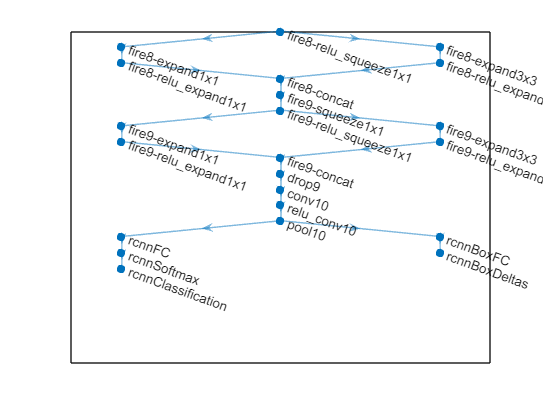

lgraph = connectLayers(lgraph,'pool10','rcnnBoxFC');
featureExtractionLayer = 'fire5-concat';

lgraph = removeLayers(lgraph, 'pool5');


outputSize = [14 14]

outputSize =     17    17



roiPool = roiMaxPooling2dLayer(outputSize,'Name','roiPool');

lgraph = addLayers(lgraph, roiPool);

lgraph = connectLayers(lgraph, featureExtractionLayer,'roiPool/in');
lgraph = connectLayers(lgraph, 'roiPool','fire6-squeeze1x1');


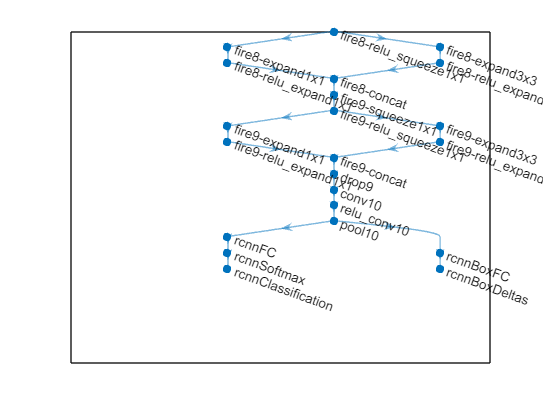

roiInput = roiInputLayer('Name','roiInput');
lgraph = addLayers(lgraph, roiInput);

lgraph = connectLayers(lgraph, 'roiInput','roiPool/roi');

ds = combine(imds, blds);
ds = transform(ds,@(data)preprocessData(data,[1280 720 3]));

inputImageSize = [1280 720 3];
numClasses = 4;

       
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 10, ...
    'InitialLearnRate', 1e-3, ...
    'MaxEpochs', 10, ...
    'CheckpointPath', tempdir,'Verbose',true);

frcnn = trainFastRCNNObjectDetector(ds, lgraph , options, ...
    'NegativeOverlapRange', [0 0.1], ...
    'PositiveOverlapRange', [0.7 1])

*******************************************************************
Training a Fast R-CNN Object Detector for the following object classes:

* bus
* car
* truck
* van

--> Extracting region proposals from training datastore...done.

Training on single GPU.
Initializing input data normalization.
|=======================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|=======================================================================================================|


|       1 |           1 |       00:21:23 |       1.6521 |       98.83% |         2.32 |          0.0010 |
|       1 |          50 |       07:57:49 |       0.3562 |       98.52% |         0.50 |          0.0010 |
|       2 |         100 |       15:33:49 |       0.2205 |       98.91% |         0.46 |          0.0010 |
|       3 |         150 |       23:02:05 |       0.2293 |       98.91% |         0.49 |          0.0010 |
|       3 |         200 |       30:51:41 |       0.2671 |       98.91% |         0.55 |          0.0010 |
|       4 |         250 |       38:29:48 |       0.2730 |       98.67% |         0.48 |          0.0010 |
|       5 |         300 |       45:53:16 |       0.3017 |       98.59% |         0.50 |          0.0010 |
|       5 |         350 |       53:25:27 |       0.3313 |       98.44% |         0.50 |          0.0010 |
|       6 |         400 |       61:14:52 |       0.2834 |       98.59% |         0.49 |          0.0010 |
|       7 |         450 |       68:48:42 |    

|       8 |         550 |       85:18:08 |       0.2375 |       98.83% |         0.50 |          0.0010 |
|       9 |         600 |       93:03:09 |       0.2601 |       98.83% |         0.50 |          0.0010 |
|      10 |         650 |      100:56:04 |       0.2464 |       98.59% |         0.46 |          0.0010 |
|      10 |         700 |      108:57:38 |       0.2638 |       98.83% |         0.53 |          0.0010 |
|      10 |         720 |      111:50:47 |       0.1980 |       98.98% |         0.50 |          0.0010 |
|=======================================================================================================|
Training finished: Max epochs completed.

Detector training complete.
*******************************************************************



frcnn =   fastRCNNObjectDetector with properties:

            ModelName: 'bus'
              Network: [1×1 DAGNetwork]
    RegionProposalFcn: @rcnnObjectDetector.proposeRegions
           ClassNames: {'bus'  'car'  'truck'  'van'  'Background'}
        MinObjectSize: [9 9]


function data = preprocessData(data,targetSize)
scale = targetSize(1:2)./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize(1:2));
bboxes = round(data{2});
data{2} = bboxresize(bboxes,scale);
end